# Equilibria of First Order ODEs

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

## Equilibria

The zero-dimensional energy balance model (EBM) predicts trends in the Earth's mean global surface temperature $T$ as a function of time $t$. An estimation of the EBM described in [Part1_SlopeFields.mlx](matlab: edit Part1_SlopeFields.mlx) (note that the script must be on the MATLAB Search Path for this link to work) is


$$\frac{dT}{dt} = a(0.5 -  0.2 \tanh(26.5 - 0.1T)) - b T^4$$


Consider the solutions to the EBM plotted on the slope field:

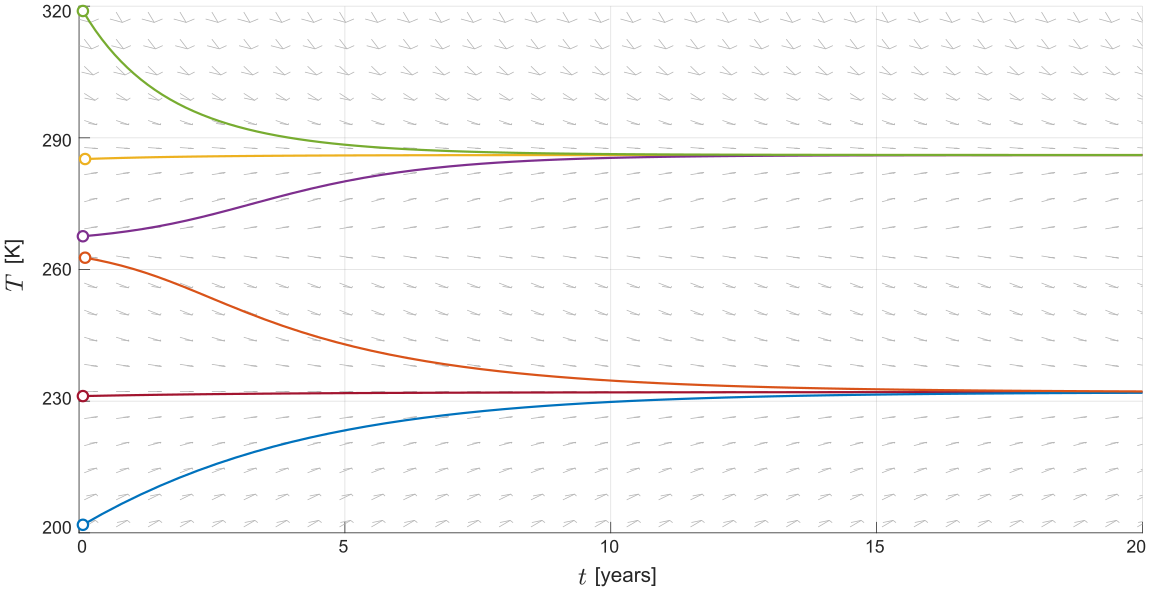

Notice that solutions starting from high, low, and intermediate temperatures tend toward the same two $T$ values. These values are known as equilibria and they have important implications for the climate model.

**Definition.** An *equilibrium* of an autonomous first order ODE is any value of the dependent variable $y$ where the derivative is zero. Consider the first order ODE


$$y'(t) = f(y)$$


The equilibria are located at

$y'(t) = 0$, or equally: $f(y) = 0$. 

If you graph the function $f(y)$, the zeros of the function are the equilibria.

 **Example. **Find the equilibria of


$$\frac{dx}{dt} = \sin(2x)$$


**Solution. **Equilibria occur where $x'(t) = 0$. To find these points, you can set the right-hand-side (RHS) to zero:


$$\sin(2x) = 0$$


Since $\sin(u)  = 0$ if $u = \pi k$ for integer $k$, this is zero wherever

$2x = \pi k$   or   $x = \frac{\pi k}{2}$.

The plot below shows the graph of $f(x) = \sin(2x)$ and the equilibria, which occur where the derivative is zero.

 
sin2xPlot % Helper function that generates the plot

**  Reflect.** 

- After solving an ODE, it is common to plot the solution $x(t)$ against the independent variable $t$. How is this graph different from that?

- The graph of $x'$ vs $x$ can be confusing because it does not show a solution curve. Why is it plotted instead of solution curves?

   **Activity. **

- Open the Slope Field app. For instructions on how to obtain and use the app, visit the [GitHub repository](https://github.com/MathWorks-Teaching-Resources/Phase-Plane-and-Slope-Field).

- In the Slope Field app, plot the field for $x' = \sin(2x)$ and generate several solutions. 

- How do the equilibria identified in the previous example appear in the slope field?

- Check your answer by clicking the checkbox below, which shows the equilibria plotted on the slope field.

plotEquilibria(false) % Plots the slope field with the equilibrium solutions

**  Reflect.** 

- Equilibria appear as horizontal lines in the slope field. These are constant solutions to the ODE. Is it possible to have an equilibrium appear as something besides a horizontal line?

- Do solutions always approach an equilibrium?

- Is there more than one type of equilibrium?

** Exercise. **Find the equilibria of 


$$y' = y-3$$


Write your answer as a comma separated list (e.g. 1,4) in the space provided.

yeq = [ ];
checkEquilibria(yeq) % Checks your answer

**  Reflect.** 

- Why is the $y$-value at which $y'(t) = 0$ called an equilibrium?

- In most sciences, the word equilibrium defines a state where two opposing forces or actions have been balanced so that there is no net change. Is that the case in the ODE $x'(t) = \sin(2x)$? In $y' = y-3$? If so, what terms of the equation have been balanced to produce zero net change?

    **Activity. **In this activity, you will identify equilibria of an ODE by clicking on the graph of its derivative.

- Select a function from the drop down menu.

- Click on the graph where each equilibrium occurs.

The graph plots $y' = f(y)$ against $y$. 

syms y
dydt = cos(y) + sin(y); n = 3; z = [-5*pi/4,-pi/4,3*pi/4];

findEquilibriaActivity(dydt,n,z) % This helper generates the activity

## **Stability**

Equilibria of first order autonomous ODEs can be characterized by their *stability*. There are three stability classifications:

- *Stable***: **nearby solutions approach the equilibrium.

- *Semi-stable*: nearby solutions approach from one direction and diverge in the other.

- *Unstable***: **nearby solutions diverge in both directions.

Consider the slope field for $x' = (x-2)(x-5)$ shown below. 

- Notice that there are two equilibria: $x = 2, 5$.

- The solutions with $x(0) = 2$ and $x(0)=5$ are constant, because $x' = 0$ if $x = 2$ or $5$.

- **Question**: are the equilibria stable or unstable?

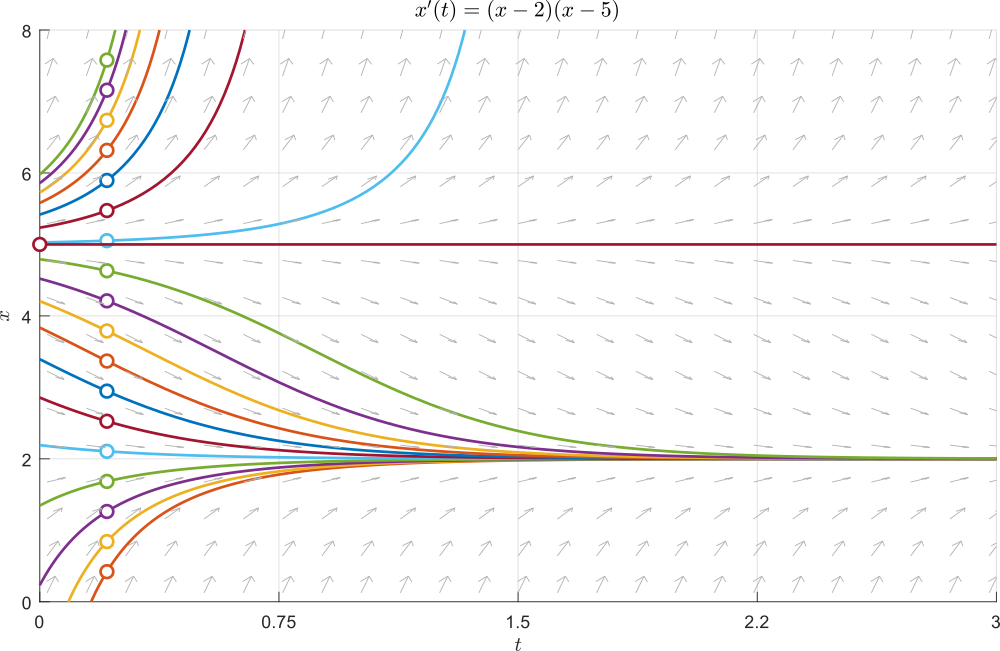

**Answer**: The equilibria through $x = 5$ is unstable: nearby solutions diverge from the equilibrium. The equilibrium at $x = 2$ is stable: nearby solutions approach it.

** Exercise. **Find the equilibria of the ODE and classify them as stable, semi-stable, or unstable. You can use the slope field app to plot nearby solutions to help you decide.

    
$$z' = (z-2)^2$$


zSolution(false) % Click to show the solution

## **Phase line portraits**

The phase line portrait is a simple way to graph equilibria and characterize their stability. Consider the ODE $x' = (x-2)(x-5)$ whose solutions were plotted above. The graph of the derivative $x'$ against $x$ appears as a parabola:

 
xm2xm5plot % Helper function that generates the plot

Notice that the derivative is zero at $x = 2$ and $x = 5$. The neighboring values of the derivative indicate which direction the solutions will head:

- $x < 2$: positive derivative. Solutions move to the right (toward $x=2$).

- $2<x<5$: negative derivative. Solutions move to the left (toward $x=2$ and away from $x = 5$).

- $x > 5$: positive derivative. Solutions move to the right (away from $x = 5$).

All of this information can be captured concisely in a phase line diagram:

    

- The arrows show the direction that the solutions head (this is based on the derivative graph).

- The points represent the equilibria.

It is easy to see from the phase line that $x = 2$ is a stable equilibrium point and $x = 5$ is unstable. It is also informative to plot the phase line together with the slope field.

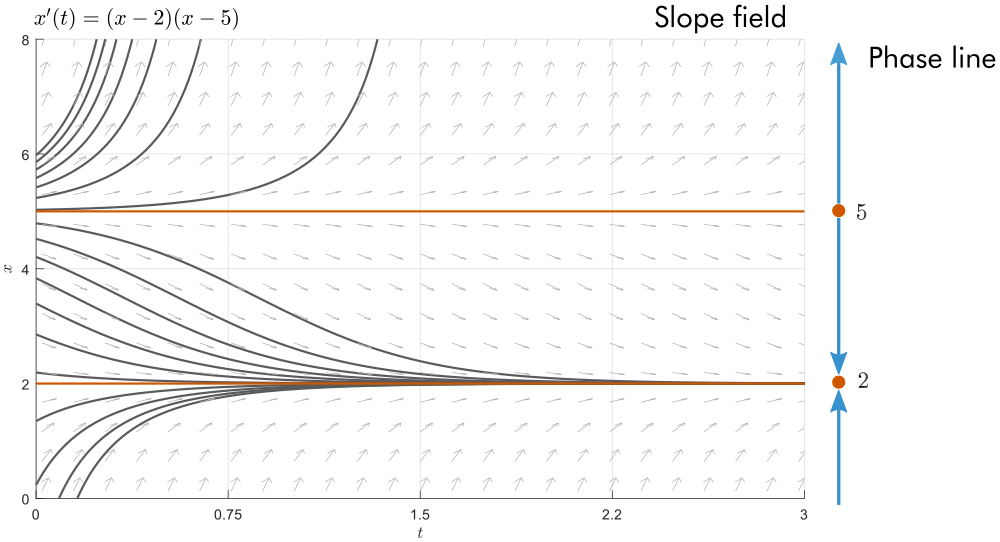

*Plotting the phase line alongside the slope field is revealing; the phase line summarizes the behavior of the ODE and its solutions.*

** Exercise. **For the ODE $z' = (z-2)^2$ complete the following:

**Task 1.** Plot the graph of the derivative $z'$ as a function of $z$. Vectors containing $z$ and $z'%$ have already been created: `z` and `zprime`. All you need to do is plot them against each other. To do so, use the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) function with the syntax:

The green text starting with a % is a comment and not necessary to create the plot.

z = linspace(0,5,500);
zprime = (z-2).^2;
% Write your code here



**Task 2. **Label the axes of your plot as z and z'. To do this, use the [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html) and [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html) functions with the syntax:

% Write your code here


 

**Task 3. **Use the plot created in the previous task to draw the phase line for $z' = (z-2)^2$ by hand and then classify the equilibrium as stable, unstable, or semi-stable.

**  Reflect.** 

- What characteristic of the zero of the derivative identifies the equilibrium as semi-stable?

- So far, you have practiced three different methods for visually analyzing autonomous ODEs: (1) the slope field (and solutions), (2) the graph of $x'$ vs $x$, and (3) the phase line. Which visualization do you find gives you the clearest idea about where the equilibria are and what the overall trends of the solutions are?

** Application. **The energy balance model (EBM) estimates the change of temperature on the surface of the Earth through


$$\frac{dT}{dt} = a(0.5 -  0.2 \tanh(26.5 - 0.1T)) - b T^4$$


where $t$ is the time in years and the parameters are $a = 55$ and $b = 5.7 \cdot 10^{-9}$.

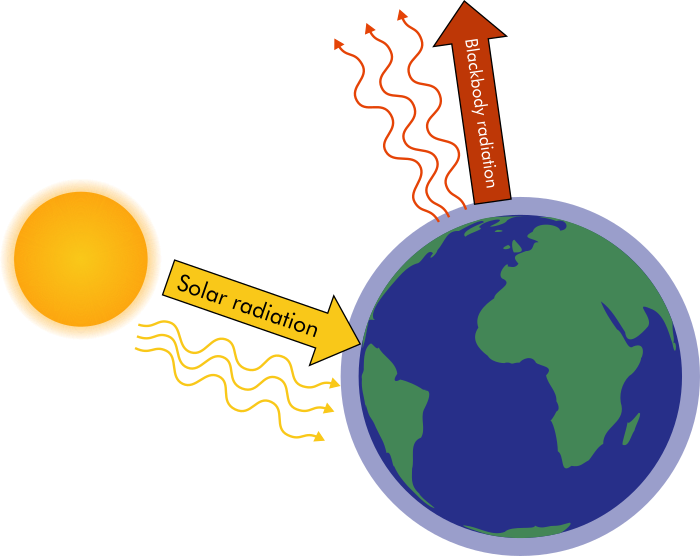

*The EBM ODE has two terms: one that represents absorbed radiation from the sun: *$a(0.5 -  0.2 \tanh(26.5 - 0.1T))$*and one that models outgoing blackbody radiation: *$- b T^4$*.*

**Task 1. **Plot the derivative $T'$ against $T$ in the space below and label the axes. 

% You can use T and Tprime defined here
a = 55;
b = 5.7e-9;
T = linspace(200,350,500);
Tprime = a*(0.5 - 0.2*tanh(26.5 - 0.1*T)) - b*T.^4;

% Write your code here to plot T vs Tprime




% This code adjusts the axes of your plot
set(gca,"XAxisLocation","Origin","YAxisLocation","Origin")
box off
axis([200 350 -10 10])

**Task 2. **Hover over the graph, and the plot tools will appear. Use the **Data Tips** tool to estimate the equilibria of the EBM ODE.

    

 If the data tip is unresponsive, pop the figure out of the live script using  and then use the **Data Tips** tool in the figure window.

 Write the equilibria in the space below to check your answer. Separate equilibria with commas, e.g., `220, 230, 300`.

eq = [ ];
checkEBMEq(eq) % Checks your answer

**Task 3. ** Draw the phase line portrait for the EBM ODE and classify the equilibria. Check your answers by clicking the checkbox below.

showEBMEquilibria(false) % Click to show the solution

**  Reflect.** 

- Based on the equilibria and their stability, how many possible steady-states does this model predict for the mean global surface temperature of the Earth?

- In the history of the Earth, has there been more than one steady temperature state? If so, which state is the Earth in now, and at what point in history was it in a different state?

- This model predicts that the Earth will always remain in the same state once it reaches it. But we know that isn't true. Like all models, this model does not incorporate the full reality (and this model is, in-fact, extremely simplified). What relevant physical factors are not accounted for by this model?

**Activities**

function findEquilibriaActivity(dydt,n,z)
    % Generates an activity for finding equilibria of the functions
    % defined in the dropdown menu
    f = figure("visible","on");
    yvec = linspace(-5,5,500);
    fplot(dydt)
    
    axis([-5 5 -5 5])
    xlabel("y")
    ylabel("y'")

    title("Click to select " + num2str(n) + " equilibrium point(s)")
    set(gca,"XAxisLocation","Origin","YAxisLocation","Origin")
    eq = [];
    for k = 1:n
        roi = drawpoint;
        eq(k) = roi.Position(1);
    end

    f2 = figure;
    copyobj(f.Children,f2)
    close(f)
    hold on
    plot(z,z*0,"x","markersize",12,"LineWidth",2)
    hold off
    
    disp("You identified equilibria at: y = " + num2str(sort(eq)))
    disp("The true equilibria are at: y = " + num2str(sort(z)))
end

**Visualizations**

function plotEquilibria(checked)
    % Plots slope field and equilibria
    if(checked)
        % helper function that generates the slope field
        plotDirectionFieldOrientationOnly(@(t,x)sin(2*x),[0,8],[-4,4],15); 
        
        axis tight
        xlimits = get(gca,"XLim");
        t = linspace(0,xlimits(2),500);
        
        xlabel("$t$","interpreter","latex")
        ylabel("$y$","interpreter","latex")
        box off
        hold on 
        cls = lines(2);
        c = cls(2,:);
        for n = -2:2
          plot(t,t*0+pi*n/2,"--","color",c) 
        end
        hold off
    end
end

function sin2xPlot
    % Plot of sin(2x)
    syms x
    f = sin(2*x);
    eq = (-3:3)*pi/2;
    fplot(f)
    hold on
    plot(eq,eq*0,"o")
    set(gca,"XAxisLocation","Origin","YAxisLocation","Origin")
    axis([-5 5 -2 2])
    xlabel("x")
    ylabel("x'")
    hold off
end

function xm2xm5plot
    % Plots f = (x-2)*(x-5)
    x = linspace(0,7,500);
    f = (x-2).*(x-5);
    eq = [2 5];
    plot(x,f)
    hold on
    plot(eq,eq*0,"o")
    set(gca,"XAxisLocation","Origin","YAxisLocation","Origin")
    axis([0 7 -3 3])
    xlabel("x")
    ylabel("x'")
    hold off
    box off
end

function plotDirectionFieldOrientationOnly(dydt,tlim,ylim,N)
    % Creates a slope field with rescaled arrows
    [T,Y,u,v] = setupDirectionField(dydt,tlim,ylim,N);
    orientationQuiver(T,Y,u,v,1.1,gca);
end

function [T,Y,u,v] = setupDirectionField(dydt,tlim,ylim,N)
    % Sets up the slope field
    t = linspace(tlim(1),tlim(2),N);
    y = linspace(ylim(1),ylim(2),N);
    [T,Y] = meshgrid(t,y);
    derivativeField = dydt(T,Y);
    u = ones(size(T));
    v = derivativeField.*u;
    axis([tlim,ylim])
    xlabel("$t$","interpreter","latex")
    ylabel("$y$","interpreter","latex")
end

function quiverHandle = orientationQuiver(x,y,vx,vy,scale,axisHandle)
    % Generates a vector field with normalized lengths
    % Set the axis limits and figure size before calling this function
    % as it determines the scaling based on the current axes
    dataAspectRatio = axisHandle.DataAspectRatio;
    plotBoxAspectRatio = axisHandle.PlotBoxAspectRatio;
    arx = dataAspectRatio(1)./plotBoxAspectRatio(1);
    ary = dataAspectRatio(2)./plotBoxAspectRatio(2);
    mags = sqrt(vx.^2 + vy.^2);
    vx = vx./mags;
    vy = vy./mags;
    nv = sqrt( (vx.*ary).^2 + (vy.*arx).^2 );
    quiverHandle = quiver(axisHandle,x,y,vx./nv,vy./nv,scale*0.5);
end

**Checks**

function checkEBMEq(eq)
    value = [232 267 286];
    if(any(size(value)~=size(eq)))
        warning("Your answer does not have the correct number of equilibria.")
        return
    end
    if( all( abs(sort(eq)-sort(value))<1) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result closely enough.")
    end
end

function checkEquilibria(teq)
    isEqualCheck(3,teq)
end

function isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

**Answers**

function zSolution(showAns)
    if(showAns)
        disp("Semi-stable equilibrium at z=2")
    end
end

function showEBMEquilibria(showAns)
    if(showAns)
        disp("Stable at T = 232K, Unstable at T = 267K, Stable at T = 286K")
    end
end

**Suppressed suggestions**

 %#ok<*NBRAK>  